addpath("ControllerTesting");

Uncomment the step response you are testing

%
%Step Response R results
y = out_R.data;
t = out_R.Time;
yfinal = stepR;
S = stepinfo(y,t,yfinal)

S = struct with fields:
        RiseTime: 0
    SettlingTime: 0
     SettlingMin: 0
     SettlingMax: 0
       Overshoot: Inf
      Undershoot: 0
            Peak: 0
        PeakTime: 0


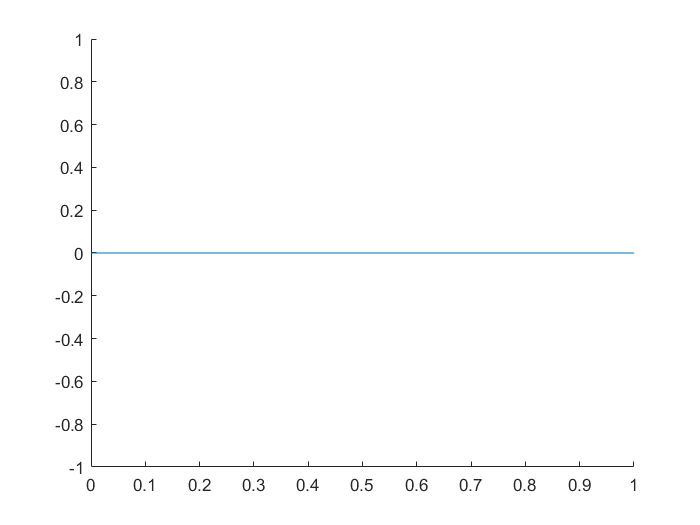

Error using xlim (line 31)
Limits must be a 2-element vector of increasing numeric values.

figure
clf;
hold on
plot(t,y)
xlim([0,S.SettlingMax])

title("Step Response of R controller")
xlabel("Time (s)")
ylabel("Response (rad)")
%}

%
%Step Response X results
y = out_X.data - initialAngleKrukX;
t = out_X.Time;
yfinal = stepX;
S = stepinfo(y,t,yfinal)

S = struct with fields:
        RiseTime: 0.0074
    SettlingTime: NaN
     SettlingMin: 0.1767
     SettlingMax: 0.3315
       Overshoot: 10.5055
      Undershoot: 0
            Peak: 0.3315
        PeakTime: 0.0161


table = "\hline Rise Time:  & " + S.RiseTime + "\\ \hline Settling Time:  & " + "none"  + ...
"\\  \hline Settling Min:  & " + S.SettlingMin + "\\ \hline Settling Max: & " + S.SettlingMin + ...
"\\ \hline Overshoot: & " + S.Overshoot + "\\ \hline Undershoot: & " + S.Undershoot + ...
"\\ \hline Peak Time:  & " + S.PeakTime + "\\ \hline"

table = "\hline Rise Time:  & 0.0074332\\ \hline Settling Time:  & none\\  \hline Settling Min:  & 0.17671\\ \hline Settling Max: & 0.17671\\ \hline Overshoot: & 10.5055\\ \hline Undershoot: & 0\\ \hline Peak Time:  & 0.016113\\ \hline"

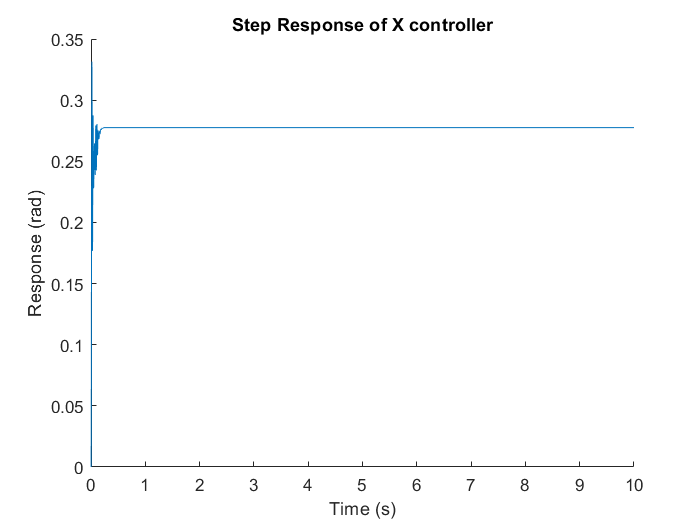

figure %  S.SettlingTime
clf;
hold on
plot(t,y)
%xlim([0,S.SettlingMax])
title("Step Response of X controller")
xlabel("Time (s)")
ylabel("Response (rad)")

%}



%
%Step Response Z results
y = out_Z.data - initialAngleKrukZ;
t = out_Z.Time;
yfinal = stepZ;
S = stepinfo(y,t,yfinal)
figure
clf;
hold on
plot(t,y)
xlim([0,S.SettlingMax])

ans = struct with fields:
        RiseTime: 0
    SettlingTime: 0
     SettlingMin: 0
     SettlingMax: 0
       Overshoot: Inf
      Undershoot: 0
            Peak: 0
        PeakTime: 0


title("Step Response of Z controller")
xlabel("Time (s)")
ylabel("Response (rad)")
%}


